Лабораторна №4

Виконала: Щербина Софія ФФ-41

Варіант: 13

1. За допомогою мікрофону ввести у комп'ютер аудіосигнал (назвіть свої прізвище, ім’я та групу). Відтворити (прослухати) введену інформацію. 

clear; close all;
fs = 8192;
t = 5;
y_recorder = audiorecorder;
disp("Start Record");

Start Record


recordblocking(y_recorder, t);
disp("Stop record");

Stop record



myRecording = getaudiodata(y_recorder);
play(y_recorder);
pause(t + 1);

2. Змінити частоту дискретизації fs для пришвидшення та уповільнення відтворення запису та відтворити отримані сигнали.

disp('Slowed-down audio');

Slowed-down audio


soundsc(myRecording, fs/2);
pause(t*2 + 1);

disp('Sped-up audio');

Sped-up audio


soundsc(myRecording, fs*2);
pause(t/2 + 1);

3. Записати введене аудіо у вигляді wav-файлу та mat-файлу. Вивести інформацію про отриманий wav-файл.

filename = 'lab4_audio.wav';
audiowrite(filename, myRecording, fs);
save('lab4_audio_data.mat', 'myRecording', 'fs');
info = audioinfo(filename);
disp('Audio File Information:');

Audio File Information:


disp(info);

             Filename: 'C:\Users\Софія\OneDrive\Робочий стіл\4 семестр\cm\lab4_audio.wav'
    CompressionMethod: 'Uncompressed'
          NumChannels: 1
           SampleRate: 8192
         TotalSamples: 40000
             Duration: 4.8828
                Title: []
              Comment: []
               Artist: []
        BitsPerSample: 16



4. Побудувати графік сигналу та його спектрограму, а також амплітудний та фазовий спектри.

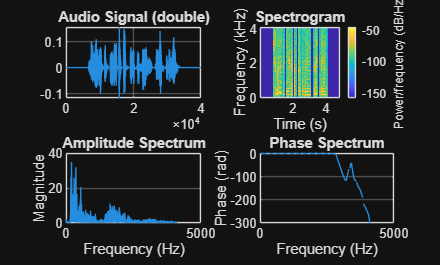

[yy, fs_read] = audioread(filename);
figure('Name', 'Audio Signal Analysis');

subplot 221
plot(myRecording); grid on;
title('Audio Signal (double)');

subplot 222
spectrogram(yy, 256, 128, [], fs_read, 'yaxis');
title('Spectrogram');

aspec = abs(fft(yy));
aspec = aspec(1:floor(end/2));
afreq = (fs_read/2)*(1:length(aspec))/length(aspec);
subplot 223
plot(afreq, aspec); grid on;
title('Amplitude Spectrum');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

fspec = phasez(fft(yy));
fspec = fspec(1:floor(end/2));
ffreq = (fs_read/2)*(1:length(fspec))/length(fspec);
subplot 224
plot(ffreq, fspec); grid on;
title('Phase Spectrum');
xlabel('Frequency (Hz)');
ylabel('Phase (rad)');

5. Завантажити файл сигналу у Signal Analyzer Toolbox та на його прикладі дослідити можливості даного Toolbox, зокрема, отримати відповідні графіки, спектрограми тощо. 

signalAnalyzer(yy, 'SampleRate', fs_read);

6 * . До аудіосигналу з п.1 додати шум (будь-якою функцією), відфільтрувати зашумлений звуковий сигнал та порівняти отриманий сигнал з початковим (шляхом порівняння відповідних графіків).

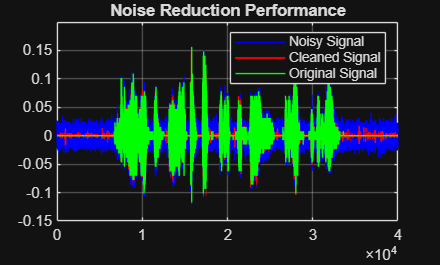

noise = 0.01 * randn(size(yy)); 
noisy_signal = yy + noise;

cleaned_signal = wdenoise(noisy_signal, floor(log2(length(noisy_signal))));

figure('Name', 'Signal Denoising Comparison');
plot(noisy_signal, 'b'); hold on;
plot(cleaned_signal, 'r', 'LineWidth', 1);
plot(myRecording, 'g');
legend('Noisy Signal', 'Cleaned Signal', 'Original Signal');
title('Noise Reduction Performance');
grid on;

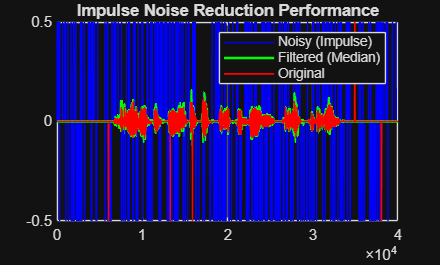


% 222

noise_density = 0.01;
noisy_signal = myRecording;

num_spikes = round(noise_density * length(myRecording));
spike_indices = randi(length(myRecording), num_spikes, 1);

noisy_signal(spike_indices) = 0.5 * (2 * (rand(num_spikes, 1) > 0.5) - 1);
% disp('Playing audio with impulse noise (clicks)...');
% sound(noisy_signal, fs);
% pause(t + 1);

cleaned_signal = medfilt1(noisy_signal, 3); 

figure('Name', 'Impulse Noise Reduction');
plot(noisy_signal, 'b', 'DisplayName', 'Noisy (Impulse)'); 
hold on;
plot(myRecording, 'g', 'LineWidth', 1.5, 'DisplayName', 'Original');
plot(cleaned_signal, 'r', 'LineWidth', 1, 'DisplayName', 'Filtered (Median)');
legend('Noisy (Impulse)', 'Filtered (Median)', 'Original');
title('Impulse Noise Reduction Performance');
grid on;

Висновок: 

Для видалення гауссового шуму обрала **вейвлет-денойзинг** (wdenoise) . Вейвлет-перетворення розкладає сигнал на різні частотні рівні , що дозволяє виділити та видалити шум, зберігаючи при цьому дрібні деталі голосу.

Аналіз отриманого графіка «Noisy vs Cleaned» показав, що вейвлет-фільтрація  «стиснула» амплітуду шумових коливань, наблизивши форму очищеного сигналу до вихідного .

Для очищення сигналу застосувала **медіанний фільтр** . Він ефективно відкидає аномальні піки (викиди), не розмиваючи при цьому різкі переходи корисного сигналу голосу.

Порівняльний аналіз графіків показав, що фільтр успішно ідентифікував та видалив імпульсні сплески. Червона лінія відфільтрованого сигналу майже повністю збіглася з оригінальною зеленою лінією, що свідчить про високу якість відновлення даних.